# This is Q4 of the assignment

n = 7;
cutoff_freq = 1;                    % Wc
f = (1/cutoff_freq)/(2*pi);                   

[z,p,k] = butter(n,2*pi*f,'low','s');
[num,den] = zp2tf(z,p,k);

## Part (i) of the assignment

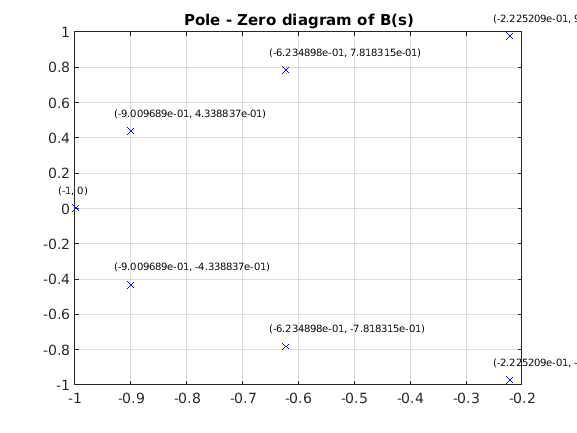

len_p = length(p);

for i = 1:len_p
    plot(real(p(i)),imag(p(i)),'bX')
    textString1 = sprintf('(%d, %d)', real(p(i)), imag(p(i)));
    text(real(p(i))-0.03, imag(p(i))+0.1, textString1, 'FontSize', 7);
    hold on
end

grid on
title('Pole - Zero diagram of B(s)') 

Marking the co-ordinate axis for better view of stability.

x_abscissa = [-5 4]

x_abscissa =     -5     4


y_abscissa = [0 0]

y_abscissa =      0     0


plot(x_abscissa,y_abscissa,'color', 'black')
xlabel('Real Axis')

x_ord = [0 0]

x_ord =      0     0


y_ord = [-3 3]

y_ord =     -3     3


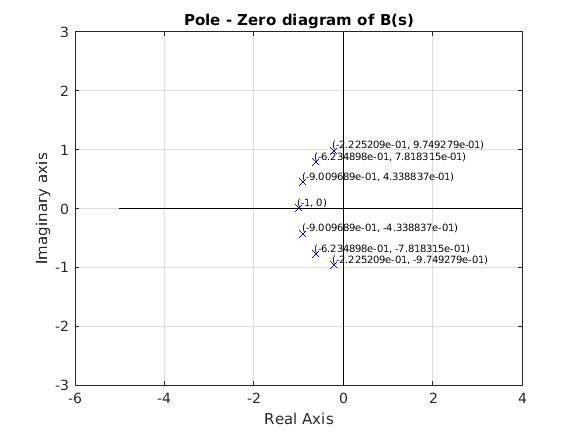

plot(x_ord,y_ord,'color', 'black')
ylabel('Imaginary axis')

Creating the circles now

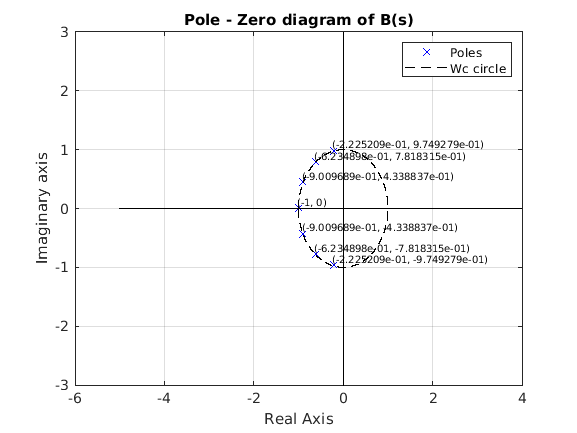

% for unit circle:
a = -pi:0.001:pi;
x_u_cir = cos(a);
y_u_cir = sin(a);

plot(x_u_cir,y_u_cir,'k--')
legend('Poles', '','','','','','','','','Wc circle');
hold off;

## Part ( ii ) of the question

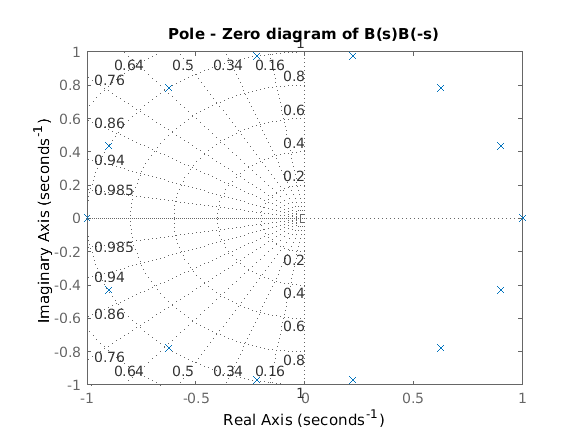

Bs = tf(num,den);
Bs_c = ctranspose(Bs);
x = Bs*Bs_c;
pzmap(x);
grid on
title('Pole - Zero diagram of B(s)B(-s)') 

## Part (iii) of the question

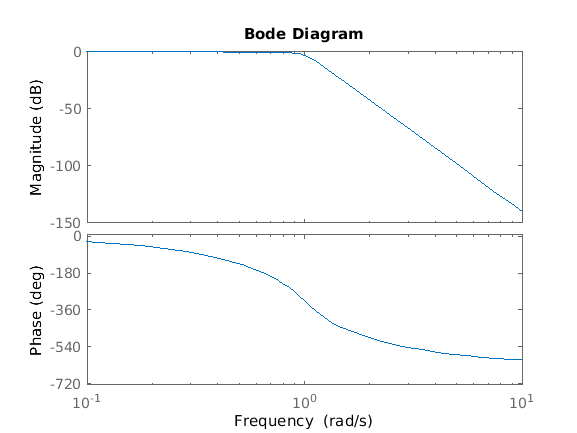

bode(Bs);


display(Bs);            % Transfer function 

Bs =
 
                                       1
  ---------------------------------------------------------------------------
  s^7 + 4.494 s^6 + 10.1 s^5 + 14.59 s^4 + 14.59 s^3 + 10.1 s^2 + 4.494 s + 1
 
Continuous-time transfer function.

